# Calcolo dei guadagni

## Setup iniziale dell'ambiente

clear
clc
digits(4)

%load('WS_VAB_wb_0.mat','A','B','C','D','r');
load('WS_VAB_wb_0_5.mat','A','B','C','D','r','J_r');
Ts = 0.0001;

## Analisi stabilità in anello aperto

Studio dell'asintotica stabilità tramite gli autovalori della matrice A: come noto dalla teoria, il sistema è asintoticamente stabile se gli autovalori hanno tutti parte reale negativa; è instabile invece se è presente almeno un autovalore con parte reale strettamente positiva.

A_real = double(A);
B_real = double(B);
C_real = double(C);
D_real = double(D);

sys = ss(A_real,B_real,C_real,D_real); % Same of G
sys_SISO = ss(A_real,B_real,[0,0,1,0],[0]);

A_real = double(A);
B_real = double(B);
C_real = double(C);
D_real = double(D);

states = {'phi' 'phi_dot' 'theta' 'theta_dot'};
inputs = {'Cm'};
outputs = {'phi' 'phi_dot' 'theta' 'theta_dot'};
sys = ss(A_real,B_real,C_real,D_real,'statename',states,'inputname',inputs,'outputname',outputs); % Same of G
sys_d = c2d(sys,Ts, 'tustin')


sys_d =
 
  A = 
               x1          x2          x3          x4
   x1           1      0.0001  -7.614e-08  -3.807e-12
   x2           0           1   -0.001523  -7.614e-08
   x3           0           0           1      0.0001
   x4           0           0   0.0005439           1
 
  B = 
               Cm
   x1   1.375e-08
   x2    0.000275
   x3  -1.306e-09
   x4  -2.612e-05
 
  C = 
                      x1          x2          x3          x4
   phi                 1       5e-05  -3.807e-08  -1.904e-12
   phi_dot             0           1  -0.0007614  -3.807e-08
   theta               0           0           1       5e-05
   theta_dot           0           0    0.000272           1
 
  D = 
                      Cm
   phi         6.875e-09
   phi_dot     0.0001375
   theta       -6.53e-10
   theta_dot  -1.306e-05
 
Sample time: 0.0001 seconds
Discrete-time state-space model.



A_d = sys_d.a;
B_d = sys_d.b;
C_d = sys_d.c;
D_d = sys_d.d;

## Analisi grafiche

eig(A_real)

ans =          0
         0
    2.3322
   -2.3322


Come si vede il sistema non è asintoticamente stabile per la presenza di autovalori con parte reale non strettamente positiva.

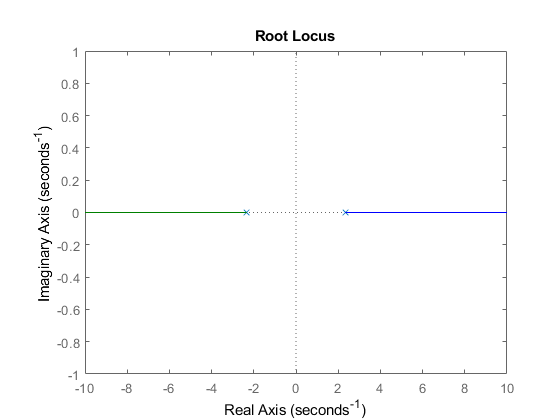

rlocus(sys_SISO)

Dal luogo delle radici si vede come sia impossibile, per il sistema ad anello aperto, andare a stabilizzare il polo che sta nel semipiano reale, variando il guadagno (questo a conferma di quanto detto in precedenza).

M_r = ctrb(sys_SISO) % Matrice di raggiungibilità

M_r =          0    2.7498         0    3.9776
    2.7498         0    3.9776         0
         0   -0.2612         0   -1.4207
   -0.2612         0   -1.4207         0


rank(M_r)

ans = 4

M_o = obsv(sys_SISO) % Matrice di osservabilità

M_o =          0         0    1.0000         0
         0         0         0    1.0000
         0         0    5.4392         0
         0         0         0    5.4392


rank(M_o)

ans = 2

Si vede come il sistema, in anello aperto, non sia asintoticamente stabile (come previsto), dalle analisi sugli autovalori e sui poli.

Lo stato del sistema, nel nostro caso, risulta essere accessibile, poichè sono misurazioni che possono essere direttamente realizzate per mezzo di tecniche di sensor fusion.

## Posizionamento poli continue

Per ora vogliamo controllare solamente l'angolo $\theta \;$, e quindi ci poniamo in una condizione di sistema SISO (input la coppia motrice, output l'accelerazione $\ddot{\theta \;}$):


$$\left\lbrace \begin{array}{c}
x\left(t\right)=Ax{\left(t\right)}+Bu\left(t\right)\\
y{\left(t\right)}=Cx{\left(t\right)}+Du\left(t\right)
\end{array}\right\rbrace$$


Utilizzando la legge di controllo, basata su uno ***state feedback controller, ***è:


$$u{\left(t\right)}=-Kx{\left(t\right)}+w{\left(t\right)}$$


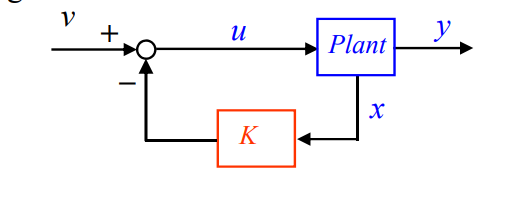

Per la scelta della matrice K


$$x{\left(t\right)}=Ax{\left(t\right)}+Bu{\left(t\right)}=Ax{\left(t\right)}+B{\left(-Kx{\left(t\right)}+w{\left(t\right)}\right)}\to legge\ di\ controllo\ in\ anello\ chiuso$$



$$=Ax{\left(t\right)}-BKx{\left(t\right)}+Bw\left(t\right)={\left(A-BK\right)}x{\left(t\right)}+Bw{\left(t\right)}$$



$$A_{cl} =A-BK=matrice\;di\;stato\;in\;closed-loop$$


Per andare a calcolare questo vettore dei poli K, possiamo utilizzare il comando ***place***.

Per fare ciò ci atteniamo ai parametri richiesti per entrambi i poli, ovvero:

- Smorzamento $=\xi =0\ldotp 7$

- Pulsazione naturale polo $=\omega {\;}_{n\;} =2\bullet \pi \bullet f_{\textrm{propria}}$

In generale sappiamo che


$$G{\left(S\right)}=\frac{\omega {\;}_n^{2\;} }{s^2 +2\xi \omega {\;}_n s+\omega {\;}_n^{2\;} }=\frac{1}{1+2∙\frac{\textrm{𝜉}}{{\textrm{𝜔}}_n }s+\frac{s^2 }{{\textrm{𝜔}}_n^2 }}$$


Per trovare i poli mi basta risolvere l'equazione al denominatore, trovando i valori di s che l'annullano:

syms xsi wn1 wn2 s;
% Definisco le funzioni di trasferimento
dd_1 = s^2 + s * 2 * xsi * wn1 + wn1^2 == 0

$$dd\_1 = s^{2}+2\,\mathrm{xsi}\,s\,{\mathrm{wn}}_{1}+{{\mathrm{wn}}_{1}}^{2}=0$$

dd_2 = s^2 + s * 2 * xsi * wn2 + wn2^2 == 0

$$dd\_2 = s^{2}+2\,\mathrm{xsi}\,s\,{\mathrm{wn}}_{2}+{{\mathrm{wn}}_{2}}^{2}=0$$

sol_dd_1 = solve(dd_1, s);
sol_dd_2 = solve(dd_2, s);

Definisco la pulsazione naturale per primo polo, destinato al controllo più veloce per l'angolo $\theta \;\ldotp$

% fn1 = 20; % [Hz]
fn1 = 0.2; % [Hz]
w1 = 2*pi*fn1; % [rad / s]

Definisco i parametri anche per il secondo polo, invece più lento e destinato a $\phi \;\ldotp$

% fn2 = 2; % [Hz]
fn2 = 0.02; % [Hz]
w2 = 2*pi*fn2; % [rad / s]

Definisco anche lo smorzamento per i poli

e =0.7; % Smorzamento

Sostituisco i parametri numeri di pulsazione e smorzamento nelle soluzione dei poli:

pol_1 = subs(sol_dd_1,{xsi,wn1},{e,w1})

$$pol\_1 = \left(\begin{array}{c} -\frac{7\,\pi }{25}+\frac{\pi \,\sqrt{51}\,\mathrm{i}}{25}\\ -\frac{7\,\pi }{25}-\frac{\pi \,\sqrt{51}\,\mathrm{i}}{25} \end{array}\right)$$

pol_2 = subs(sol_dd_2,{xsi,wn2},{e,w2})

$$pol\_2 = \left(\begin{array}{c} -\frac{7\,\pi }{250}+\frac{\pi \,\sqrt{51}\,\mathrm{i}}{250}\\ -\frac{7\,\pi }{250}-\frac{\pi \,\sqrt{51}\,\mathrm{i}}{250} \end{array}\right)$$

pol_1_real = double(pol_1)

pol_1_real =   -0.8796 + 0.8974i
  -0.8796 - 0.8974i


pol_2_real = double(pol_2)

pol_2_real =   -0.0880 + 0.0897i
  -0.0880 - 0.0897i


K_c = place(A_real,B_real,[pol_1_real', pol_2_real'])

K_c =    -0.0023   -0.0278  -28.1397   -7.7022



%%%%%%%%% TODO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% B_aug=[B_real,[0;0;0;0];0,1];
% A_aug = [A_real,[0;0;0;0];[0,-1,0,0],1];
% K_i = place(1,1,real(pol_2_real(1))/10)
% K_aug = place(A_aug,B_aug,poles)
%%%%%%%%% TODO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Calcolo la nuova matrice A in anello chiuso con i valori di K:

A_cl = A_real - B_real * K_c;

Verifico che i nuovi autovalori abbiano parte reale negativa.

eig(A_cl)

ans =   -0.8796 + 0.8974i
  -0.8796 - 0.8974i
  -0.0880 + 0.0897i
  -0.0880 - 0.0897i


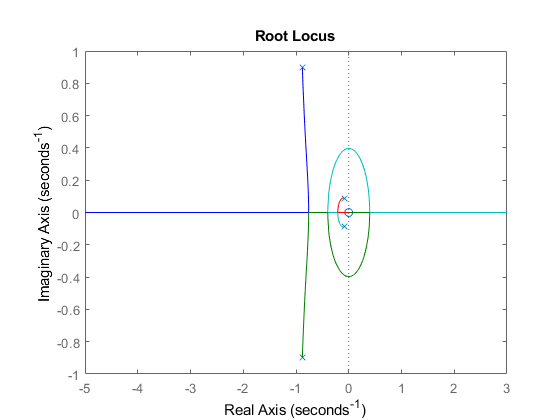

sys_cl = ss(A_cl,B_real,[0,0,1,0],[0]);
rlocus(sys_cl)

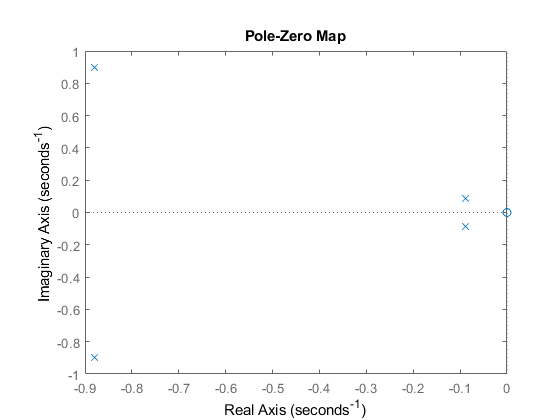

pzmap(sys_cl)

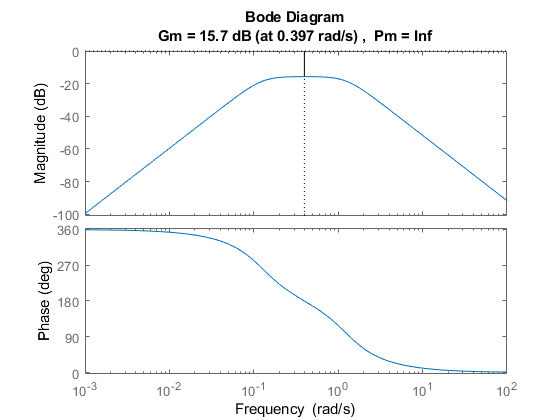

margin(sys_cl)

Si vede quindi come, soprattutto dal luogo delle radici, che abbiamo ottenuto la possibilità di andare a muovere i poli nel semipiano a parte reale negativa.

Posso utilizzare un'altra tecnica per realizzare il place dei poli (LQR - Regolatore Lineare Quadratico) che rappresenta una soluzione ottima per il pole placement:

Q = eye(4);
R = 1;
K_lqr = lqr(A_real,B_real,Q,R)

K_lqr =    -1.0000   -2.3459 -115.4689  -54.9525



A_cl_lqr = A_real - B_real * K_lqr;

Verifico che i nuovi autovalori abbiano parte reale negativa.

eig(A_cl_lqr)

ans =   -3.3303 + 0.0000i
  -2.1436 + 0.0000i
  -1.2143 + 0.2519i
  -1.2143 - 0.2519i


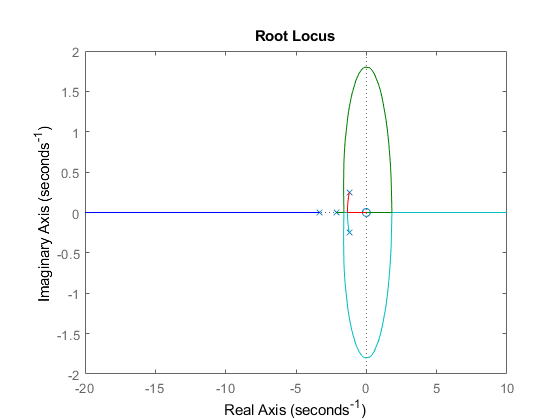

sys_cl_lqr = ss(A_cl_lqr,B_real,[0,0,1,0],[0]);
rlocus(sys_cl_lqr)

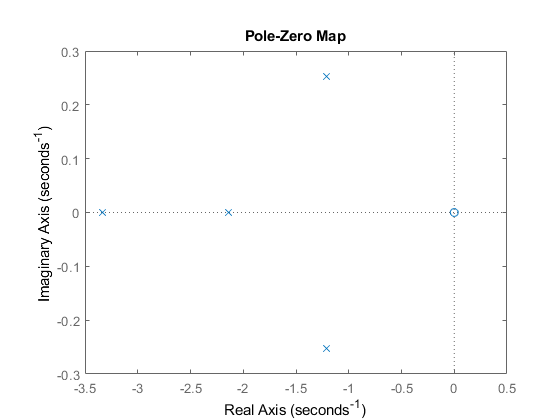

pzmap(sys_cl_lqr)

## Posizionamento dei poli discreti

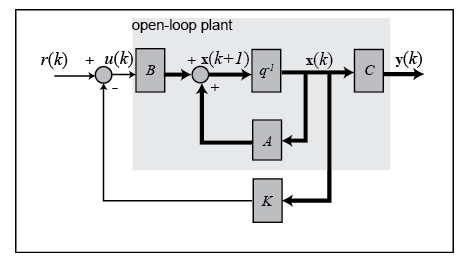

syms xsi wn1 wn2 s;
dd_1 = s^2 + s * 2 * xsi * wn1 + wn1^2 == 0;
dd_2 = s^2 + s * 2 * xsi * wn2 + wn2^2 == 0;
sol_dd_1 = solve(dd_1, s);
sol_dd_2 = solve(dd_2, s);

Definisco la pulsazione naturale per primo polo, destinato al controllo più veloce per l'angolo $\theta \;\ldotp$

% fn1 = 20; % [Hz]
fn1 = 0.2; % [Hz]
w1 = 2*pi*fn1; % [rad / s]

Definisco i parametri anche per il secondo polo, invece più lento e destinato a $\phi \;\ldotp$

% fn2 = 2; % [Hz]
fn2 = 0.02; % [Hz]
w2 = 2*pi*fn2; % [rad / s]

Definisco anche lo smorzamento per i poli

e =0.7; % Smorzamento

Sostituisco i parametri numeri di pulsazione e smorzamento nelle soluzione dei poli:

pol_1 = subs(sol_dd_1,{xsi,wn1},{e,w1});
pol_2 = subs(sol_dd_2,{xsi,wn2},{e,w2});
pol_1_continuos = double(pol_1)

pol_1_continuos =   -0.8796 + 0.8974i
  -0.8796 - 0.8974i


pol_2_continuos = double(pol_2)

pol_2_continuos =   -0.0880 + 0.0897i
  -0.0880 - 0.0897i


Aggiungiamo il terzo polo per la retroazione su $\phi {\;}_{\textrm{primo}} \;$ad una decade di distanza da polo più lento interno.

pol_3_continuos = real(pol_2_continuos(1))/10

pol_3_continuos = -0.0088

Spesso l'approccio che si segue è quello di andare a settare la posizione dei poli inizialmente nel dominio a tempo continuo e successivamente mappare

i poli setteti nel continuos-time domain nel discrete-time domain utilizzando


$$z=\exp \left(\textrm{sTs}\right)$$


poles_1_disc=exp(pol_1_continuos.* Ts);
poles_2_disc=exp(pol_2_continuos.* Ts);
poles_3_disc=exp(pol_3_continuos.* Ts);
K_d = place(A_d,B_d,[poles_1_disc', poles_2_disc']);

A_aug = [A_d,[0;0;0;0];[0,-1,0,0],1]

A_aug =     1.0000    0.0001   -0.0000   -0.0000         0
         0    1.0000   -0.0015   -0.0000         0
         0         0    1.0000    0.0001         0
         0         0    0.0005    1.0000         0
         0   -1.0000         0         0    1.0000


B_aug=[B_d,[0;0;0;0];0,1]

B_aug =     0.0000         0
    0.0003         0
   -0.0000         0
   -0.0000         0
         0    1.0000


poles = [poles_1_disc', poles_2_disc',poles_3_disc]

poles =    0.9999 - 0.0001i   0.9999 + 0.0001i   1.0000 - 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i


K_aug = place(A_aug,B_aug,poles)

K_aug =    -0.0023   -0.0278  -28.1390   -7.7028         0
         0   -1.0000         0         0    0.0000


K_i = K_aug(2,5)

K_i = 8.7965e-07

Calcolo la nuova matrice A in anello chiuso con i valori di K:

A_cl = A_d - B_d * K_d;

Verifico che i nuovi autovalori abbiano parte reale negativa.

eig(A_cl)

ans =    1.0000 + 0.0000i
   1.0000 - 0.0000i
   0.9999 + 0.0001i
   0.9999 - 0.0001i


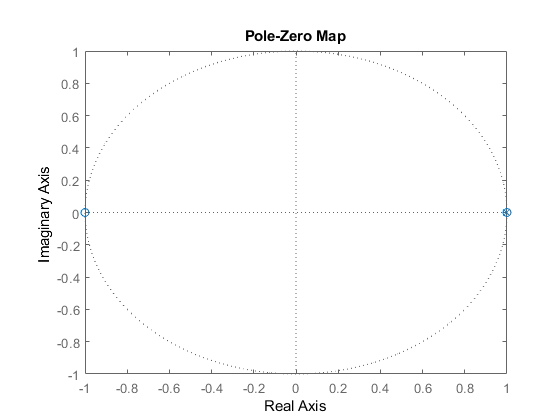

sys_cl = ss(A_cl,B_d,[0,0,1,0],[0], Ts);
pzmap(sys_cl)

## Salvataggio

save('Gains.mat', 'K_c', 'K_d')